# Initializer.mlx

## This file specifies the simulation parameters, stores the outputs from the PSSE simulation and plots them.

#### This script changes all interpretation parameters to LaTeX.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

#### Specify simulation parameters: system name, sampling rate, window size, etc. and fish out desired output parameters from the PSSE outfile.

tic
system_name = 'ieee9'

system_name = 'ieee9'

sampling_rate = 0.3/30;
T = 3%Window size in seconds

T = 3

W = T/sampling_rate

W = 300

bifurcation_limit  = 0.90

bifurcation_limit = 0.9000

folder_name = 'saved_outputs/'; %subfolder where data will be stored

variableList = {'system_name',...
    'sampling_rate','T','W','bifurcation_limit'};
firstRow = {system_name, sampling_rate, T, W, bifurcation_limit};
nominalValuesTable = array2table(firstRow, 'VariableNames',variableList);
tableName = strcat(folder_name, 'nominalValuesTable_', system_name, '.csv')

tableName = 'saved_outputs/nominalValuesTable_ieee9.csv'

% tableName = strcat(folder_name, 'nominalValuesTable_', system_name)
writetable(nominalValuesTable, tableName);

xlsxname = strcat(system_name,'_outfile.xlsx')

xlsxname = 'ieee9_outfile.xlsx'

opts = detectImportOptions(xlsxname, 'NumHeaderLines', 3);
opts.VariableNamingRule = 'modify';
xlsxtable = readtable(xlsxname, opts);


string0 = 'Time';
string1 = 'POWR';
string2 = 'BUS';
string3 = 'PLOD';
string4 = 'FREQ';
string5 = 'VOLT';
string6 = 'CKT';
string7 = 'MVA';

varNames = xlsxtable.Properties.VariableNames;
times = xlsxtable(:, contains(varNames,string0));
times.Properties.VariableNames = {'time'};
rows = times.time > 1.0;
times = times.time(times.time > 1.0);
% segregating the 'normal' run from 
% the constant load increment run

colors = [ [18,14,249]
    [67,127,29] 
    [230,43,52]
   [7,7,7]]/255;


pgens = xlsxtable(rows, contains(varNames, string1) ...
    & contains(varNames, string2));
pgensArr = table2array(pgens);
save(strcat(folder_name,'pgens_',system_name,'.mat'), 'pgensArr');

ploads = xlsxtable(rows, contains(varNames, string3));
ploadsArr = table2array(ploads);
save(strcat(folder_name,'ploads_',system_name,'.mat'), 'ploadsArr');

freqs = xlsxtable(rows,contains(varNames,string4));
freqsArr = table2array(freqs);
save(strcat(folder_name,'freqs_',system_name,'.mat'), 'freqsArr');

volts = xlsxtable(rows, contains(varNames, string5));
voltsRawArr = table2array(volts);
save(strcat(folder_name,'voltsRaw_',system_name,'.mat'), 'voltsRawArr');

% numIterations = size(volts,1)
numBuses = size(volts,2)

numBuses = 9

volts = volts{:,:};
[voltageSamplingStartsFrom, startIdx] = max(volts);
bifurcationIdx = find(volts < bifurcation_limit,...
    1, 'first')

bifurcationIdx = 8438

lastIdx = size(volts, 1)

lastIdx = 10724

voltsTruncatedArr = volts(1:bifurcationIdx, :);
save(strcat(folder_name,'voltsTruncated_', ...
    system_name, '.mat'),'voltsTruncatedArr');

mvaflows = xlsxtable(rows, contains(varNames, string6) ...
    & contains(varNames, string7));
mvaflowNames = mvaflows.Properties.VariableNames;
indicesToDelete = [];
for i = 1:length(mvaflowNames)
    if mvaflowNames{i}(4) > mvaflowNames{i}(7)
        indicesToDelete = [indicesToDelete i];
    end
end
mvaflowNames(indicesToDelete) = [];
mvaflowsArr = mvaflows{:,mvaflowNames};
save(strcat(folder_name,'mvaflows_', system_name,'.mat'), 'mvaflowsArr');


#### Calculate Branch Current Flows.

busesInEachBranch = [1 2 3 4 4 5 6  7 8];
currentsArr = 1/sqrt(3)*mvaflowsArr./volts(:, busesInEachBranch);
save(strcat(folder_name,'currents_', system_name,'.mat'), 'currentsArr');

indicesToPlot1 = 1:bifurcationIdx;
xaxis1 = (bifurcationIdx - indicesToPlot1)*sampling_rate/(60);

#### Plot Bus Frequencies.

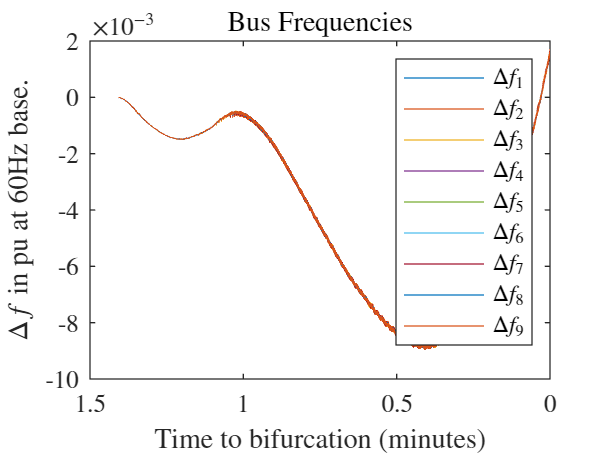

figure('Name', 'Bus Frequencies')
p1 = plot(xaxis1, freqs{indicesToPlot1,1:end});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Bus Frequencies');
ylabel1 = ylabel('$\Delta f$ in pu at 60Hz base.');
if strcmp(system_name,'ieee9')
    leg1 = legend('$\Delta f_1$', '$\Delta f_2$', '$\Delta f_3$', ...
    '$\Delta f_4$', '$\Delta f_5$', '$\Delta f_6$', ...
    '$\Delta f_7$', '$\Delta f_8$', '$\Delta f_9$');
elseif strcmp(system_name,'ieee39')
    leg1 = legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end

#### Plot Generation Values.

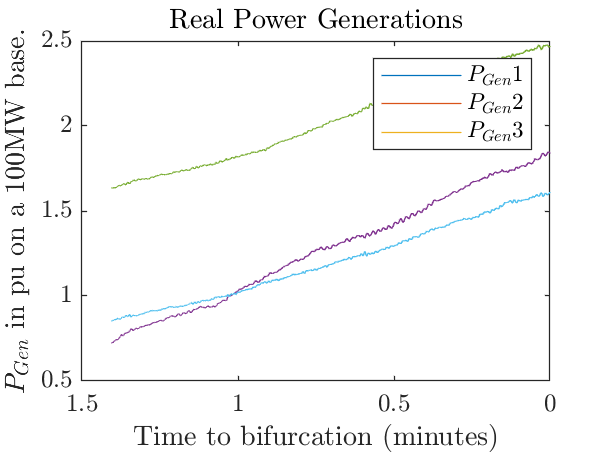

figure('Name', 'Generation Values')
p1 = plot(xaxis1, pgens{indicesToPlot1,1:end});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title('Real Power Generations');
ylabel1 = ylabel('$P_{Gen}$ in pu on a 100MW base.');
if strcmp(system_name,'ieee9')
    leg1 = legend('$P_{Gen} 1$', '$P_{Gen} 2$', '$P_{Gen} 3$');
elseif strcmp(system_name,'ieee39')
    leg1 = legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end

#### Plot Load Demand Values.

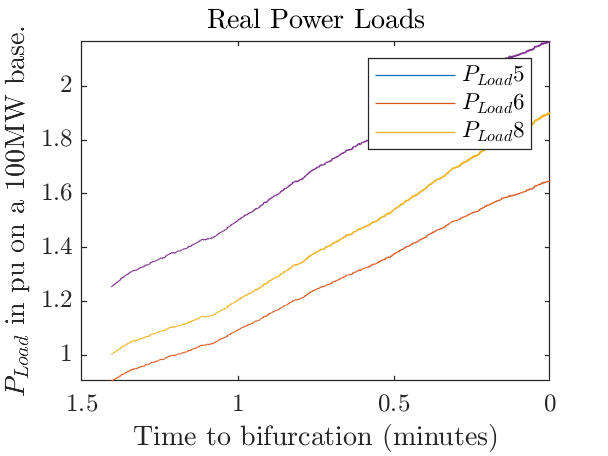

figure('Name', 'Load Values')
p2 = plot(xaxis1, ploads{indicesToPlot1,1:end});
xlabel2 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title('Real Power Loads')
ylabel2 = ylabel('$P_{Load}$ in pu on a 100MW base.');
if strcmp(system_name,'ieee9')
    leg2 = legend('$P_{Load} 5$', '$P_{Load} 6$', '$P_{Load} 8$');
elseif strcmp(system_name,'ieee39')
    leg2 = legend('$P_{Load} 1$', '$P_{Load} 231$', 'and so on');
else
    legend;
end

#### Plot Branch MVA flows.

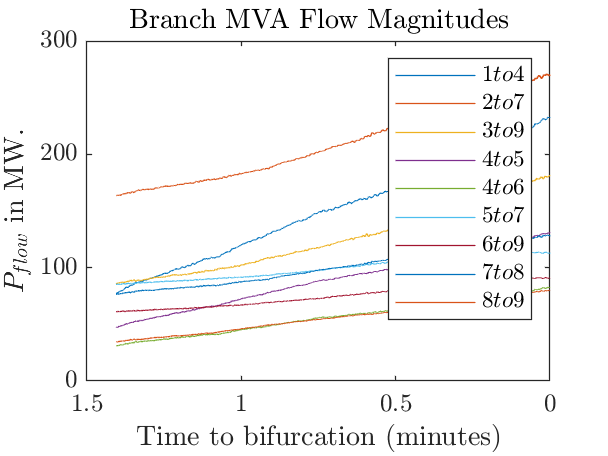

figure('Name', 'Branch MVA flows')
p1 = plot(xaxis1, ...
    mvaflowsArr(indicesToPlot1,1:end));
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Branch MVA Flow Magnitudes');
ylabel1 = ylabel('$P_{flow}$ in MW.');

labelMVAflows = {'$1 to 4$', '$2 to 7$', '$3 to 9$', ...
    '$4 to 5$', '$4 to 6$', '$5 to 7$', ...
    '$6 to 9$', '$7 to 8$', '$8 to 9$'};
name_labelMVAflows = strcat(folder_name, 'labelMVAflows_'...
    , system_name, '.mat');
save(name_labelMVAflows, "labelMVAflows");

labelGKSMVAflows = {'$GKS(1 to 4)$', '$GKS(2 to 7)$', ...
    '$GKS(3 to 9)$', '$GKS(4 to 5)$', '$GKS(4 to 6)$', ...
    '$GKS(5 to 7)$', '$GKS(6 to 9)$', '$GKS(7 to 8)$', '$GKS(8 to 9)$'};
name_labelGKSMVAflows = strcat(folder_name, 'labelGKSMVAflows_'...
    , system_name, '.mat');
save(name_labelGKSMVAflows, "labelGKSMVAflows");

labelDeltaMVAflows = {'$d(1 to 4)$', '$d(2 to 7)$', ...
    '$d(3 to 9)$', '$d(4 to 5)$', '$d(4 to 6)$', ...
    '$d(5 to 7)$', '$d(6 to 9)$', '$d(7 to 8)$', '$d(8 to 9)$'};
name_labelDeltaMVAflows = strcat(folder_name, 'labelDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelDeltaMVAflows, "labelDeltaMVAflows");

labelARDeltaMVAflows = {'$a_1(d(1 to 4))$', '$a_1(d(2 to 7))$', ...
    '$a_1(d(3 to 9))$', '$a_1(d(4 to 5))$', '$a_1(d(4 to 6))$', ...
    '$a_1(d(5 to 7))$', '$a_1(d(6 to 9))$', '$a_1(d(7 to 8))$', '$a_1(d(8 to 9))$'};
name_labelARDeltaMVAflows = strcat(folder_name, 'labelARDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelARDeltaMVAflows, "labelARDeltaMVAflows");

labelVarDeltaMVAflows = {'$\sigma^2(d(1 to 4))$', '$\sigma^2(d(2 to 7))$', ...
    '$\sigma^2(d(3 to 9))$', '$\sigma^2(d(4 to 5))$', '$\sigma^2(d(4 to 6))$', ...
    '$\sigma^2(d(5 to 7))$', '$\sigma^2(d(6 to 9))$', '$\sigma^2(d(7 to 8))$', '$\sigma^2(d(8 to 9))$'};
name_labelVarDeltaMVAflows = strcat(folder_name, 'labelVarDeltaMVAflows_'...
    , system_name, '.mat');
save(name_labelVarDeltaMVAflows, "labelVarDeltaMVAflows");

if strcmp(system_name,'ieee9')
    leg1 = legend(labelMVAflows);   
elseif strcmp(system_name,'ieee39')
    leg1 = legend('MVA flows missing for ieee39.');
else
    legend;
end

#### Plot Branch Currents.

figure('Name', 'Branch Current Flows')
p1 = plot(xaxis1, ...
    currentsArr(indicesToPlot1,1:end));
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Branch Current Magnitudes');
ylabel1 = ylabel('$Currents$ in A.');

labelcurrents = {'$1 to 4$', '$2 to 7$', '$3 to 9$', ...
    '$4 to 5$', '$4 to 6$', '$5 to 7$', ...
    '$6 to 9$', '$7 to 8$', '$8 to 9$'};
name_labelcurrents = strcat(folder_name, 'labelcurrents_'...
    , system_name, '.mat');
save(name_labelcurrents, "labelcurrents");

labelGKScurrents = {'$GKS(1 to 4)$', '$GKS(2 to 7)$', ...
    '$GKS(3 to 9)$', '$GKS(4 to 5)$', '$GKS(4 to 6)$', ...
    '$GKS(5 to 7)$', '$GKS(6 to 9)$', '$GKS(7 to 8)$', '$GKS(8 to 9)$'};
name_labelGKScurrents = strcat(folder_name, 'labelGKScurrents_'...
    , system_name, '.mat');
save(name_labelGKScurrents, "labelGKScurrents");

labelDeltacurrents = {'$d(1 to 4)$', '$d(2 to 7)$', ...
    '$d(3 to 9)$', '$d(4 to 5)$', '$d(4 to 6)$', ...
    '$d(5 to 7)$', '$d(6 to 9)$', '$d(7 to 8)$', '$d(8 to 9)$'};
name_labelDeltacurrents = strcat(folder_name, 'labelDeltacurrents_'...
    , system_name, '.mat');
save(name_labelDeltacurrents, "labelDeltacurrents");

labelARDeltacurrents = {'$a_1(d(1 to 4))$', '$a_1(d(2 to 7))$', ...
    '$a_1(d(3 to 9))$', '$a_1(d(4 to 5))$', '$a_1(d(4 to 6))$', ...
    '$a_1(d(5 to 7))$', '$a_1(d(6 to 9))$', '$a_1(d(7 to 8))$', '$a_1(d(8 to 9))$'};
name_labelARDeltacurrents = strcat(folder_name, 'labelARDeltacurrents_'...
    , system_name, '.mat');
save(name_labelARDeltacurrents, "labelARDeltacurrents");

labelVarDeltaVoltages = {'$\sigma^2(d(1 to 4))$', '$\sigma^2(d(2 to 7))$', ...
    '$\sigma^2(d(3 to 9))$', '$\sigma^2(d(4 to 5))$', '$\sigma^2(d(4 to 6))$', ...
    '$\sigma^2(d(5 to 7))$', '$\sigma^2(d(6 to 9))$', '$\sigma^2(d(7 to 8))$', '$\sigma^2(d(8 to 9))$'};
name_labelVarDeltaVoltages = strcat(folder_name, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");

if strcmp(system_name,'ieee9')
    leg1 = legend(labelcurrents);   
elseif strcmp(system_name,'ieee39')
    leg1 = legend('Legend Missing for ieee39');
else
    legend;
end

#### Plot Bus Voltages.

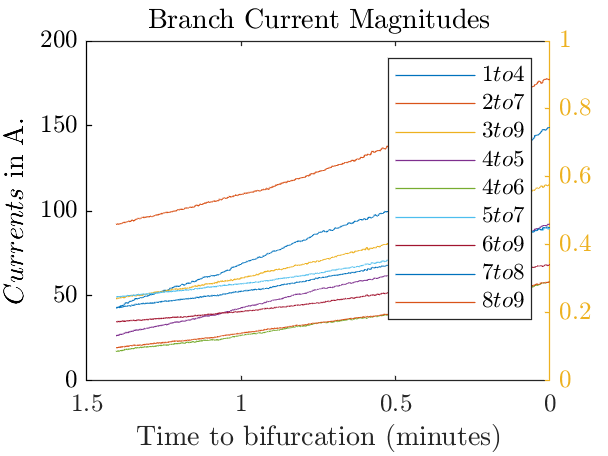

indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

% figure('Name', 'Bus Voltages')
subplot(1,1,1)

yyaxis left

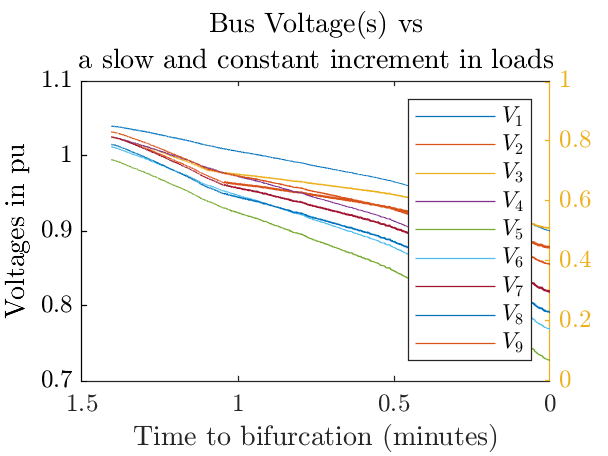


figure('Name', 'Bus Voltages')

set(gca,'xdir','reverse')
p1 = plot(xaxis1, volts(indicesToPlot1,1:end));

labelVoltages = {'$V_1$', '$V_2$', '$V_3$', '$V_4$',...
    '$V_5$', '$V_6$', '$V_7$', '$V_8$', '$V_9$'};
name_labelVoltages = strcat(folder_name, 'labelVoltages_'...
    , system_name, '.mat');
save(name_labelVoltages, "labelVoltages");

labelGKSVoltages = {'$GKS(V_1)$', '$GKS(V_2)$', '$GKS(V_3)$', '$GKS(V_4)$',...
    '$GKS(V_5)$', '$GKS(V_6)$', '$GKS(V_7)$', '$GKS(V_8)$', '$GKS(V_9)$'};
name_labelGKSVoltages = strcat(folder_name, 'labelGKSVoltages_'...
    , system_name, '.mat');
save(name_labelGKSVoltages, "labelGKSVoltages");

labelDeltaVoltages = {'$d(V_1)$', '$d(V_2)$', '$d(V_3)$', '$d(V_4)$',...
    '$d(V_5)$', '$d(V_6)$', '$d(V_7)$', '$d(V_8)$', '$d(V_9)$'};
name_labelDeltaVoltages = strcat(folder_name, 'labelDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelDeltaVoltages, "labelDeltaVoltages");

labelARDeltaVoltages = {'$a_1(d(V_1))$', '$a_1(d(V_2))$', '$a_1(d(V_3))$', '$a_1(d(V_4))$',...
    '$a_1(d(V_5))$', '$a_1(d(V_6))$', '$a_1(d(V_7))$', '$a_1(d(V_8))$', '$a_1(d(V_9))$'};
name_labelARDeltaVoltages = strcat(folder_name, 'labelARDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelARDeltaVoltages, "labelARDeltaVoltages");

labelVarDeltaVoltages = {'$\sigma^2((d(V_1))$', '$\sigma^2(d(V_2))$', '$\sigma^2(d(V_3))$', '$\sigma^2(d(V_4))$',...
    '$\sigma^2(d(V_5))$', '$\sigma^2(d(V_6))$', '$\sigma^2(d(V_7))$', '$\sigma^2(d(V_8))$', '$\sigma^2(d(V_9))$'};
name_labelVarDeltaVoltages = strcat(folder_name, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
save(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");


legend(labelVoltages);
ylabel1 = ylabel('Voltages in pu');
yticks1 = yticks;
set(gca,'ycolor',colors(1,:))
set(gca,'xdir','reverse')

yyaxis right

xlabel1 = xlabel('Time to bifurcation (minutes)');


title('Bus Voltage(s) vs', ...
    'a slow and constant increment in loads');



toc

Elapsed time is 6.531438 seconds.
